- Loading Fashion Mnist data  

images = loadMNISTImages("C:\Users\Carlos\Desktop\fashion-mnist\data\fashion\train-images-idx3-ubyte")

images =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

labels = loadMNISTLabels("C:\Users\Carlos\Desktop\fashion-mnist\data\fashion\train-labels-idx1-ubyte")

labels =      9
     0
     0
     3
     0
     2
     7
     2
     5
     5


im = reshape(images, 28, 28, 60000);

im = im(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    0.0039         

labels = uint16(labels);
class(labels(1,1))

ans = 'uint16'

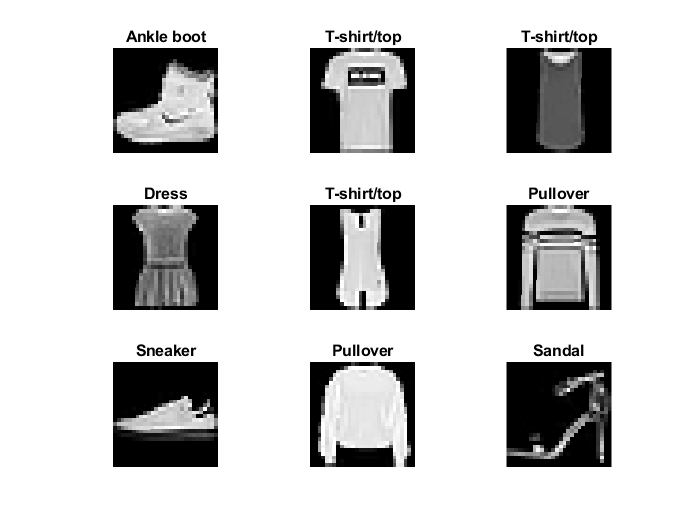

a = uint16
9

a = uint16
0

a = uint16
0

a = uint16
3

a = uint16
0

a = uint16
2

a = uint16
7

a = uint16
2

a = uint16
5

classNames = ["T-shirt/top", "Trouser", "Pullover", "Dress", "Coat", "Sandal", "Shirt", "Sneaker", "Bag", "Ankle boot"];
figure()
for i = 1:9
    a = labels(i,1)
    subplot(3,3, i); imshow(im(:,:,i)); title(classNames(a+1)); 
end

layers = [
    imageInputLayer([28 28 1],"Name","imageinput")
    convolution2dLayer([3 3],16,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    convolution2dLayer([3 3],32,"Name","conv2","Padding","same")
    regressionLayer("Name","regressionoutput")];